# Chapter 6, Section 5 (Part 2)

Let's do some examples of Least Squares Solutions.

# Example #1

Given


$$A=\pmatrix{1 & -1\cr 1 & 1\cr 2 & 1}\qquad\text{and}\qquad\textbf b=\pmatrix{2\cr 1\cr 1}$$


perform each of the following tasks.

- Find the least squares solution of $A\textbf x=\textbf b$.

- Find the orthogonal projection of $\textbf b$ onto $W=\text{col}(A)$ and the decomposition of the vector $\textbf b=\textbf w_1+\textbf w_2$, where $\textbf w_1\in W$ and $\textbf w_2\in W^\bot$.

**Solution:** Set up the equation $A\textbf x=\textbf b$ and multiply both sides by $A^T$.


$$\begin{array}{rcl}
\pmatrix{1 & -1\cr 1 & 1\cr 2 & 1}\pmatrix{x_1\cr x_2}&=&\pmatrix{2\cr 1\cr 1}\\
\pmatrix{1 & 1 & 2\cr -1 & 1 & 1}\pmatrix{1 & -1\cr 1 & 1\cr 2 & 1}\pmatrix{x_1\cr x_2}&=&\pmatrix{1 & 1 & 2\cr -1 & 1 & 1}\pmatrix{2\cr 1\cr 1}\\
\end{array}$$


Simplify.


$$\pmatrix{6 & 2\cr 2 & 3}\pmatrix{x_1\cr x_2}=\pmatrix{5\cr 0}$$


We can check this step with Matlab.

A=[1 -1;1 1;2 1];
b=[2;1;1];
A.'*A

ans =      6     2
     2     3


A.'*b

ans =      5
     0


Same as our hand-calculations. Now, multiply both sides by the inverse.


$$\begin{array}{rcl}
\pmatrix{x_1\cr x_2}&=&\pmatrix{6 & 2\cr 2 & 3}^{-1}\pmatrix{5\cr 0}\\
\pmatrix{x_1\cr x_2}&=&\frac{1}{14}\pmatrix{3 & -2\cr -2 & 6}\pmatrix{5\cr 0}\\
\pmatrix{x_1\cr x_2}&=&\frac{1}{14}\pmatrix{15\cr -10}\\
\pmatrix{x_1\cr x_2}&=&\pmatrix{15/14\cr -5/7}
\end{array}$$


We can check our solution with Matlab.

xhat=A\b

xhat =     1.0714
   -0.7143


Is that the same as our hand-calculated answer?

[15/14;-5/7]

ans =     1.0714
   -0.7143


The answer is "Yes". Now, the projection of $\textbf b$ onto $W=\text{col}(A)$ is:


$$\begin{array}{rcl}
\textbf w_1&=&A\hat{\textbf x}\\
\textbf w_1&=&\pmatrix{1 & -1\cr 1 & 1\cr 2 & 1}\pmatrix{15/14\cr -5/7}\\
\textbf w_1&=&\pmatrix{1 & -1\cr 1 & 1\cr 2 & 1}\pmatrix{15/14\cr -10/14}\\
\textbf w_1&=&\frac{1}{14}\pmatrix{1 & -1\cr 1 & 1\cr 2 & 1}\pmatrix{15\cr -10}\\
\textbf w_1&=&\frac{1}{14}\pmatrix{25\cr 5\cr 20}\\
\textbf w_1&=&\pmatrix{25/14\cr 5/14\cr 10/7}
\end{array}$$


And we can check this with Matlab.

w1=A*xhat

w1 =     1.7857
    0.3571
    1.4286


Is that the same as our answer?

[25/14;5/14;10/7]

ans =     1.7857
    0.3571
    1.4286


The answer is "Yes". Now we will calculate $\textbf w_2=\textbf b-\textbf w_1$.


$$\begin{array}{rcl}
\textbf w_2&=&\textbf b-\textbf w_1\\
\textbf w_2&=&\pmatrix{2\cr 1\cr 1}-\pmatrix{25/14\cr5/14\cr20/14}\\
\textbf w_2&=&\pmatrix{28/14\cr 14/14\cr 14/14}-\pmatrix{25/14\cr5/14\cr20/14}\\
\textbf w_2&=&\pmatrix{3/14\cr 9/14\cr -6/14}\\
\textbf w_2&=&\pmatrix{3/14\cr 9/14\cr -3/7}
\end{array}$$


And we can check this with Matlab.

w2=b-w1

w2 =     0.2143
    0.6429
   -0.4286


Is this the same as our hand-calculated answer?

[3/14;9/14;-3/7]

ans =     0.2143
    0.6429
   -0.4286


The answer is "Yes". Let's draw an image to see if this makes sense.

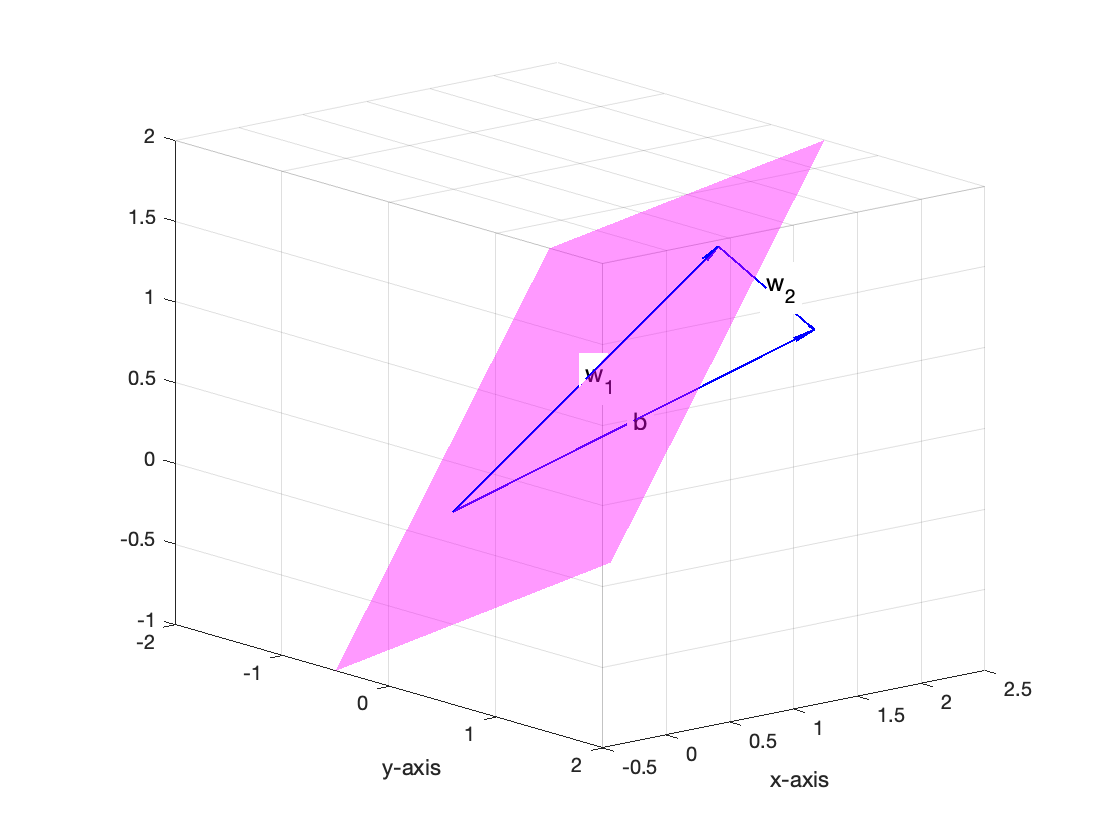

figure
hold on
s=linspace(-4,4,20);
t=linspace(-4,4,20);
[S,T]=meshgrid(s,t);
X=S-T;
Y=S+T;
Z=2*S+T;
surf(X,Y,Z,'FaceColor','m','FaceAlpha',0.4,'EdgeColor','none')
quiver3(0,0,0,b(1),b(2),b(3),0,'LineWidth',1','Color','b')
quiver3(0,0,0,w1(1),w1(2),w1(3),0,'LineWidth',1','Color','b')
quiver3(w1(1),w1(2),w1(3),w2(1),w2(2),w2(3),0,'LineWidth',1','Color','b')
grid on
axis equal
axis([-0.5,2.5,-2,2,-1,2])
xlabel('x-axis')
ylabel('y-axis')
text(0.5*b(1),0.5*b(2),0.5*b(3),'b','FontSize',12,'BackgroundColor','w')
text(0.5*w1(1),0.5*w1(2),0.5*w1(3),'w_1','FontSize',12,'BackgroundColor','w')
text(w1(1)+0.5*w2(1),w1(2)+0.5*w2(2),w1(3)+0.5*w2(3),'w_2','FontSize',12,'BackgroundColor','w')
view(40,-14)
hold off

Good visual evidence that we have done this correctly. 

# Example #2

Consider the points $(-2,-1)$, $(-1,0)$, $(1,1)$, and $(2,2)$ and perform these two tasks.

- Plot the points.

- Find the equation of the line of best fit and add it to your plot.

**Solution:** The first step is to plot the given points. Enter the x-values and the y-values in the variables x and y.

x=[-2 -1 1 2]; 
y=[-1 0 1 2];

Now we can plot these points and prettify our image.

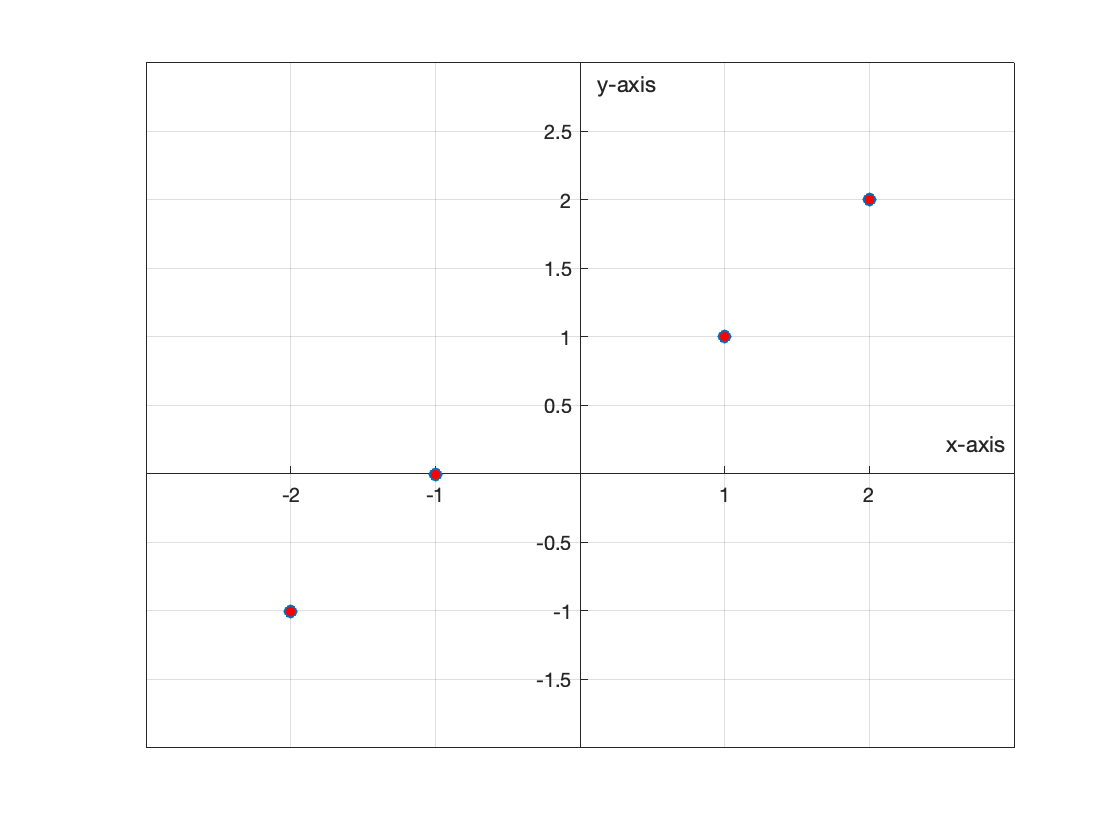

figure
plot(x,y,'o','MarkerFaceColor','r')
grid on
axis([-3,3,-2,3])
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
xlabel('x-axis')
ylabel('y-axis')

We want to fit a line of the form 


$$y=mx+b$$


 to this data. The next step is to substitute our points $(x,y)=(-2,-1)$, $(-1,0)$, $(1,1)$, and $(2,2)$ in this equation.


$$\begin{array}{rcl}
-1&=&-2m+b\\
0&=&-m+b\\
1&=&m+b\\
2&=&2m+b
\end{array}$$
 

Now, let's write this in vector form.


$$\pmatrix{-1\cr 0\cr 1\cr 2}=m\pmatrix{-2\cr -1\cr 1\cr 2}+b\pmatrix{1\cr 1\cr 1\cr 1}$$


Now we can write this in matrix form.


$$\pmatrix{-1\cr 0\cr 1\cr 2}=\pmatrix{-2 & 1\cr -1 & 1\cr 1 & 1\cr 2 & 1}\pmatrix{x\cr b}$$


Our equation now has the form $A\textbf x=\textbf b$. Let's enter $A$ and $\textbf b$ in Matlab, then row reduce the augmented matrix $[A,\textbf b]$ to see if it has a solution.

A=[-2 1;-1 1;1 1;2 1]; b=[-1;0;1;2];
rref([A,b])

ans =      1     0     0
     0     1     0
     0     0     1
     0     0     0



$$\begin{array}{rcl}
\matrix{m\ \,& b\ & \,~~}\\
\pmatrix{[1] & 0 & 0\cr 0 & [1] & 0\cr 0 & 0 & 1\cr 0 & 0 & 0}\\
\matrix{p\ & p\  & ~\,~}
\end{array}$$


Note that the third row represents the equation $0m+0b=1$, so this system is inconsistent. Since the system has no solution, let's try to find a least squares solution. Multiply both sides of the equation $A\textbf x=\textbf b$ by $A^T$.


$$\begin{array}{rcl}
\pmatrix{-2 & -1 & 1 & 2\cr 1 & 1 & 1 & 1}\pmatrix{-2 & 1\cr -1 & 1\cr 1 & 1\cr 2 & 1}\pmatrix{m\cr b}&=&\pmatrix{-2 & -1 & 1 & 2\cr 1 & 1 & 1 & 1}\pmatrix{-1\cr 0\cr 1\cr 2}\\
\pmatrix{10 & 0\cr 0 & 4}\pmatrix{m\cr b}&=&\pmatrix{7\cr 2}
\end{array}$$


We can check this with Matlab.

A.'*A

ans =     10     0
     0     4


A.'*b

ans =      7
     2


We're correct thus far. Now we multiply both sides by the inverse.


$$\begin{array}{rcl}
\pmatrix{m\cr b}&=&\pmatrix{10 & 0\cr 0 & 4}^{-1}\pmatrix{7\cr 2}\\
\pmatrix{m\cr b}&=&\frac{1}{40}\pmatrix{4 & 0\cr 0 & 10}\pmatrix{7\cr 2}\\
\pmatrix{m\cr b}&=&\frac{1}{40}\pmatrix{28\cr 20}\\
\pmatrix{m\cr b}&=&\pmatrix{28/40\cr 20/40}\\
\pmatrix{m\cr b}&=&\pmatrix{7/10\cr 1/2}
\end{array}
$$


Thus, $m=7/10$ and $b=1/2$, so our equation $y=mx+b$ is


$$y=\frac7{10}x+\frac12$$


Let's add this to our graph and see if it works.

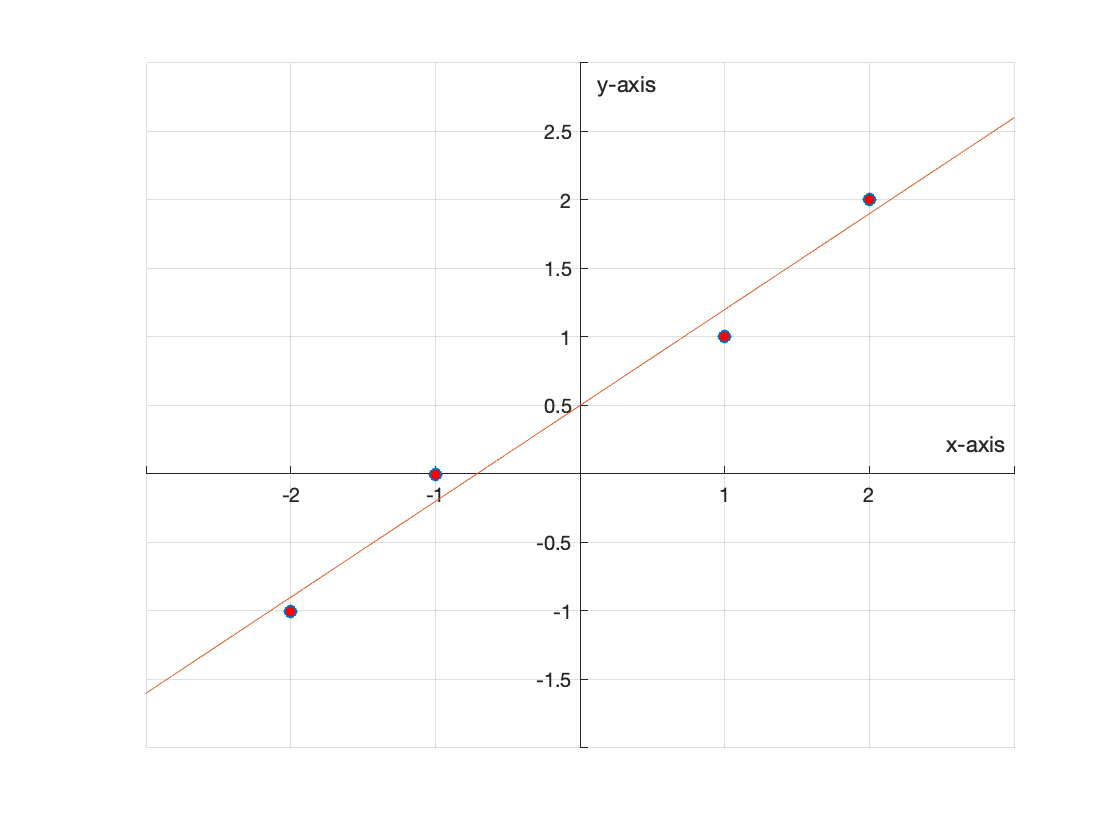

figure
hold on
plot(x,y,'o','MarkerFaceColor','r')
x=linspace(-3,3);
y=7/10*x+1/2;
plot(x,y)
grid on
axis([-3,3,-2,3])
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
xlabel('x-axis')
ylabel('y-axis')

Students in statistics call this process **linear regression**. They want to minimize the errors made by their line. Here is an image that describes the errors. 

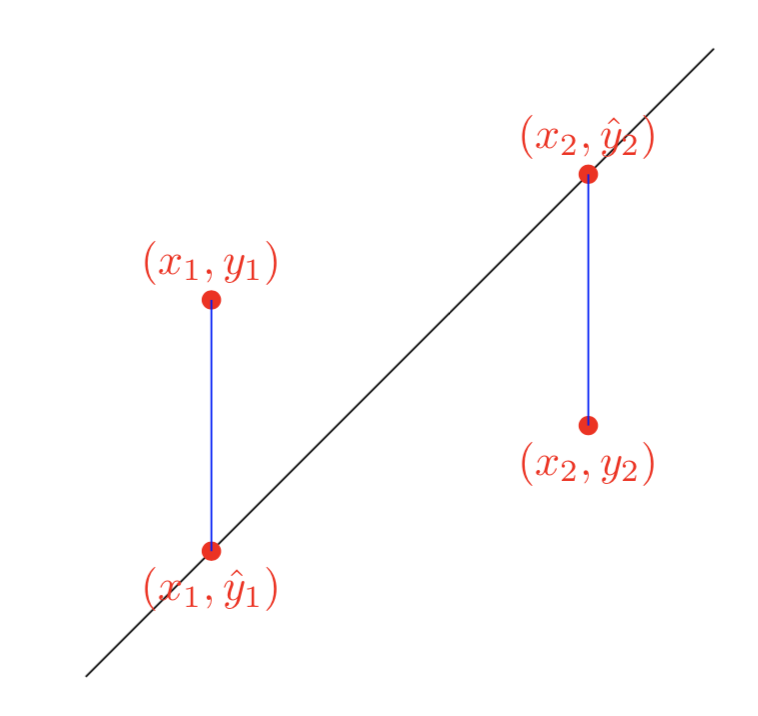

The error made at each point is defined as $y-\hat{y}$. Because some of the data points are above the line and some are below, $y-\hat{y}$ can be either positive or negative and when we add them, they can possibly cancel each other, reducing the error. Therefore, what we do is square the difference; that is, the square of the error at each point is $(y-\hat{y})^2$. The line we seek is the line that minimizes the sum of the errors. Does that sound like our least square error?

Let's enter our data again.

x=[-2 -1 1 2]; 
y=[-1 0 1 2];

Now, our equation is $y=(7/10)x+(1/2)$, which we will use to determine the $(x,\hat{y})$ values.

yhat=7/10*x+1/2;

Now, we'll calculate the $(y-\hat{y})^2$, the square of the errors.

(y-yhat).^2

ans =     0.0100    0.0400    0.0400    0.0100


Now, let's use $\textbf w_1=A\hat{\textbf x}$ to calculate the projection of $\textbf b$ on the column space of matrix $A$.

w1=A*xhat; 

Now, let's find the orthogonal component $\textbf w_2=\textbf v-\textbf w_1$, which we said was our least squares error, and square each of its elements. 

w2=b-w1;
w2.^2

ans =     0.0100
    0.0400
    0.0400
    0.0100


Wow! Same elements as in (y-yhat).^2 above. Again, nice evidence that we are doing a process called the least square process. 

# Using Matlab's polyfit Command

Let's enter our data again from Example #2.

x=[-2 -1 1 2]; 
y=[-1 0 1 2];

Now we will use Matlab's polyfit command to fit a polynomial of degree one (a line) to our data.

p=polyfit(x,y,1)

p =     0.7000    0.5000


Wow! That's the same line we got in Example #2. :-)

# Example #3

Find the equation of a polynomial of the form $y=ax^2+bx+c$ that best fits the data points $(-2,3)$, $(-1,2)$, $(1,1)$, and $(2,2)$.

**Solution: **We'll find the arithmetic difficult on this problem and we will thank Matlab for assistance. The first step is to substitute the points $(x,y)=(-2,3)$, $(-1,2)$, $(1,1)$, and $(2,2)$ into the equation


$$y=ax^2+bx+c$$


getting


$$\begin{array}{rcl}
3&=&4a-2b+c\\
2&=&a-b+c\\
1&=&a+b+c\\
2&=&4a+2b+c
\end{array}$$


which can be written in matrix form as follows.


$$\pmatrix{4 & -2 & 1\cr 1 & -1 & 1\cr 1 & 1 & 1\cr 4 & 2 & 1}\pmatrix{a\cr b \cr c}=\pmatrix{3\cr 2\cr 1\cr 2}$$


Does this system $A\textbf x=\textbf b$ have a solution? Let's set up the augmented matrix $[A,\textbf b]$ in Matlab and row reduce.

A=[4 -2 1;1 -1 1;1 1 1;4 2 1]; b=[3;;2;;1;;2];
rref([A,b])

ans =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


Note that the last row represents the equation $0a+0b+0c=1$, which doesn't have a solution. Therefore, this system is inconsistent (doesn't have a solution). So, let's find a least squares solution. The first step is to multiply both sides of the equation by $A^T$.


$$\begin{array}{rcl}
\pmatrix{4 & -2 & 1\cr 1 & -1 & 1\cr 1 & 1 & 1\cr 4 & 2 & 1}\pmatrix{a\cr b \cr c}&=&\pmatrix{3\cr 2\cr 1\cr 2}\\
\pmatrix{4 & 1 & 1 & 4\cr -2 & -1 & 1 & 2\cr 1 & 1 & 1 & 1}\pmatrix{4 & -2 & 1\cr 1 & -1 & 1\cr 1 & 1 & 1\cr 4 & 2 & 1}\pmatrix{a\cr b \cr c}&=&\pmatrix{4 & 1 & 1 & 4\cr -2 & -1 & 1 & 2\cr 1 & 1 & 1 & 1}\pmatrix{3\cr 2\cr 1\cr 2}\\
\pmatrix{34 & 0 & 10\cr 0 & 10 & 0\cr 10 & 0 & 4}\pmatrix{a\cr b\cr c}&=&\pmatrix{23\cr -3\cr 8}
\end{array}$$


That was difficult arithmetic, so let's check this step with Matlab. First we check the left-hand side.

A.'*A

ans =     34     0    10
     0    10     0
    10     0     4


That's the same as our hand-calculations. Now we check the right-hand side.

A.'*b

ans =     23
    -3
     8


That's also the same as our hand-calculations, so we are correct thus far. Now we need to solve this equation for $a$, $b$, and $c$. Here is your instructor's hand-calculations, checked at each step with Matlab.


$$\pmatrix{34 & 0 & 10 & 23\cr 0 & 10 & 0 & -3\cr 10 & 0 & 4 & 8}\ \matrix{(1/34)R_1\cr (1/10)R_2\cr ~}\qquad\longrightarrow\qquad\pmatrix{1 & 0 & 5/17 & 23/34\cr 0 & 1 & 0 & -3/10\cr 10 & 0 & 4 & 8}$$


Matlab check:

C=[34 0 10 23;0 10 0 -3;10 0 4 8];
r1=C(1,:);
r2=C(2,:);
r3=C(3,:);
C=sym([1/34*r1;1/10*r2;r3])

$$C = \left(\begin{array}{cccc} 1 & 0 & \frac{5}{17} & \frac{23}{34}\\ 0 & 1 & 0 & -\frac{3}{10}\\ 10 & 0 & 4 & 8 \end{array}\right)$$

Checks. Next,


$$\pmatrix{1 & 0 & 5/17 & 23/34\cr 0 & 1 & 0 & -3/10\cr 10 & 0 & 4 & 8}\ \matrix{~\cr ~\cr R_3-10R_1}\qquad\longrightarrow\qquad\pmatrix{1 & 0 & 5/17 & 23/34\cr 0 & 1 & 0 & -3/10\cr 0 & 0 & 18/17 & 21/17}$$


Matlab check:

r1=C(1,:);
r2=C(2,:);
r3=C(3,:);
C=[r1;r2;r3-10*r1]

$$C = \left(\begin{array}{cccc} 1 & 0 & \frac{5}{17} & \frac{23}{34}\\ 0 & 1 & 0 & -\frac{3}{10}\\ 0 & 0 & \frac{18}{17} & \frac{21}{17} \end{array}\right)$$

Checks. Next,


$$\pmatrix{1 & 0 & 5/17 & 23/34\cr 0 & 1 & 0 & -3/10\cr 0 & 0 & 18/17 & 21/17}\ \matrix{~\cr ~\cr (17/18)R_3}\qquad\longrightarrow\qquad\pmatrix{1 & 0 & 5/17 & 23/34\cr 0 & 1 & 0 & -3/10\cr 0 & 0 & 1 & 7/6}$$


Matlab check:

r1=C(1,:);
r2=C(2,:);
r3=C(3,:);
C=[r1;r2;17/18*r3]

$$C = \left(\begin{array}{cccc} 1 & 0 & \frac{5}{17} & \frac{23}{34}\\ 0 & 1 & 0 & -\frac{3}{10}\\ 0 & 0 & 1 & \frac{7}{6} \end{array}\right)$$

Checks. Next,


$$\pmatrix{1 & 0 & 5/17 & 23/34\cr 0 & 1 & 0 & -3/10\cr 0 & 0 & 1 & 7/6}\ \matrix{R_1-(5/17)R_3\cr ~\cr ~}\qquad\longrightarrow\qquad\pmatrix{1 & 0 &0 & 1/3\cr 0 & 1 & 0 & -3/10\cr 0 & 0 & 1 & 7/6}$$


Matlab check:

r1=C(1,:);
r2=C(2,:);
r3=C(3,:);
C=[r1-5/17*r3;r2;r3]

$$C = \left(\begin{array}{cccc} 1 & 0 & 0 & \frac{1}{3}\\ 0 & 1 & 0 & -\frac{3}{10}\\ 0 & 0 & 1 & \frac{7}{6} \end{array}\right)$$

Checks. Thus, our answer is $a=1/3$, $b=-3/10$, and $c=7/6$, so our second degree polynomial is:


$$p(x)=\frac13x^2-\frac3{10}x+\frac76$$


**Fast Matlab check: **Remember that Matlab's A\b command returns a least squares solution. Let's see what it gives us. Recall that we already have A and b saved above, so:

xhat=A\b

xhat =     0.3333
   -0.3000
    1.1667


Note that these are the same as the numbers in our polynomial $p(x)=\frac13x^2-\frac3{10}x+\frac76$. Here is some evidence of this claim.

[1/3;-3/10;7/6]

ans =     0.3333
   -0.3000
    1.1667


Now, let's plot this polynomial to see how well it fits the data.

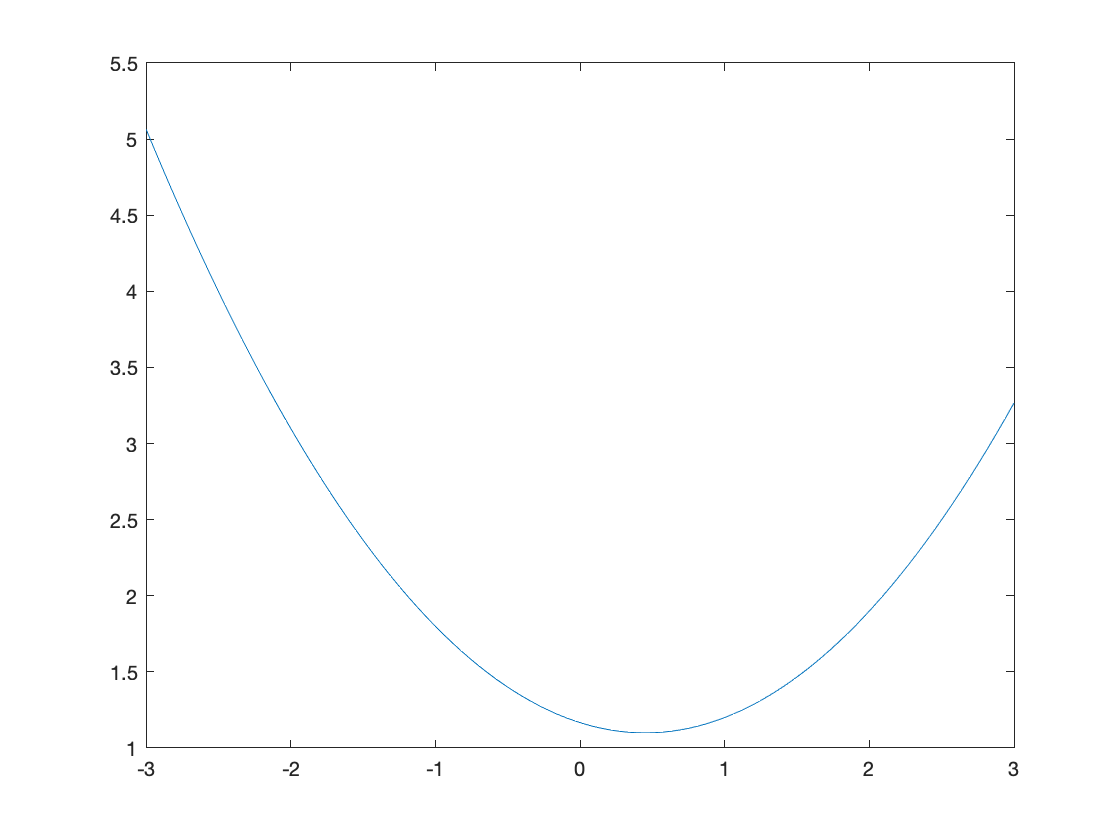

figure
x=linspace(-3,3);
y=1/3*x.^2-3/10*x+7/6;
plot(x,y)

Certainly a parabola, but what about our points? Let's add them to our image and prettify our image.

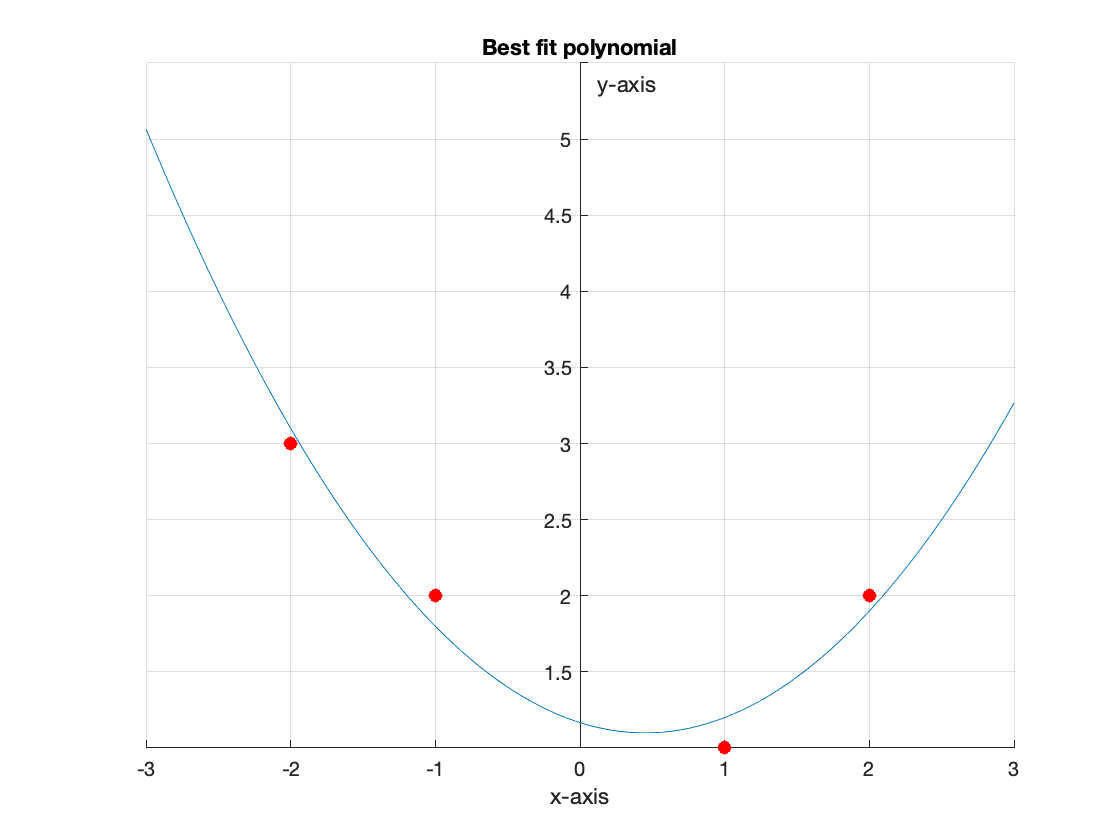

figure
hold on
x=linspace(-3,3);
y=1/3*x.^2-3/10*x+7/6;
plot(x,y)
x=[-2 -1 1 2];
y=[3 2 1 2];
plot(x,y,'ro','MarkerFaceColor','r')
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
xlabel('x-axis')
ylabel('y-axis')
title('Best fit polynomial')
hold off

Nice. :-)

# Faster Way with Matlab

Let's use Matlab's **polyfit** and **polyval **commands to perform this task quickly. First, we enter our points.

x=[-2 -1 1 2];
y=[3 2 1 2];

Now we use Matlab's **polyfit** command, this time entering a 2 to return a second degree polynomial.

p=polyfit(x,y,2)

Again, same numbers as our hand-calculations. Now we will use Matlab's **polyval** command to help us plot this answer.

figure
hold on
x=[-2 -1 1 2];

p =     0.3333   -0.3000    1.1667


y=[3 2 1 2];
p=polyfit(x,y,2);
u=linspace(-3,3);
v=polyval(p,u);
plot(u,v)
plot(x,y,'ro','MarkerFaceColor','r')
grid on
ax=gca;
ax.XAxisLocation='origin';ax.YAxisLocation='origin';
xlabel('x-axis')
ylabel('y-axis')
title('Best fit polynomial')
hold off

Same image, but very quick. :-)